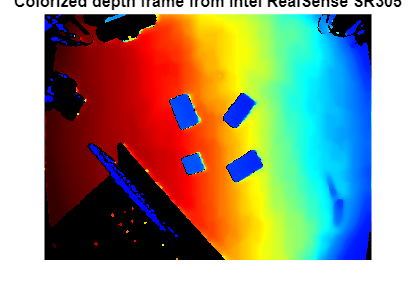

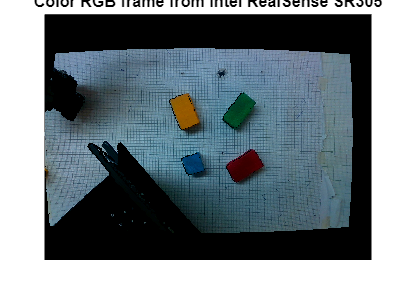

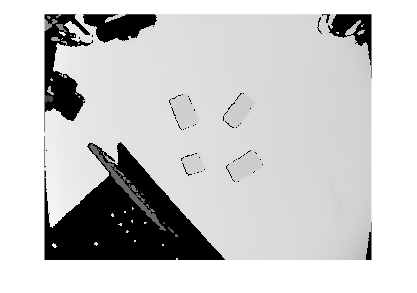

%% -------------------- 1. Load and Synchronize Resolutions --------------------
clc; clear; close all;

[imgDepth, imgRGB] = depth_example();


[rows, cols, ~] = size(imgRGB); %getting size of the RGB image

% Resize depth image to match RGB resolution
imgDepth = imresize(imgDepth, [rows, cols], 'nearest');
depthData = double(imgDepth);

% Synchronize dimensions to prevent indexing errors
[dRows, dCols] = size(depthData); %getting size of the depth image
rows = min(rows, dRows);
cols = min(cols, dCols);
imgRGB = imgRGB(1:rows, 1:cols, :);
depthData = depthData(1:rows, 1:cols);

%% -------------------- 2. Segment Red Block --------------------
imgLab = rgb2lab(imgRGB);
[L, a, b] = imsplit(imgLab);

% Refined thresholds for red
redMask = a > 20 & b > 10; 
redMask = imclose(redMask, strel('disk', 5)); 
redMask = bwareaopen(redMask, 500); 

%% -------------------- 3. PCA for Rectified Orientation --------------------
[row_pixels, col_pixels] = find(redMask); 

% PCA identifies the major spread of pixels
pixel_coords = [col_pixels, row_pixels]; 
coeff = pca(pixel_coords); 

% RECTIFICATION LOGIC:
% coeff(:,1) is the Major Axis (Longer side)
% coeff(:,2) is the Minor Axis (Shorter side)
% We want X_b along the SHORT side and Y_b along the LONG side.
x_vec = coeff(:,2); % Minor Axis as X
y_vec = coeff(:,1); % Major Axis as Y

% Ensure a Right-Hand Rule (Z must point away from camera into the table)
% If det([x_vec, y_vec]) is negative, we flip y_vec to maintain orientation
if det([x_vec, y_vec]) < 0
    y_vec = -y_vec;
end

% Theta for the rotation matrix calculation
theta_pca = atan2(x_vec(2), x_vec(1)); 

%% -------------------- 4. RANSAC Ground Plane Fitting --------------------
fx = 444.6; fy = 461.0; %testing intrinsic parameters of the camera
cx_img = cols / 2; cy_img = rows / 2;

[pxX, pxY] = meshgrid(1:cols, 1:rows);

% Table plane points = valid depth data MINUS the block itself
validTableIdx = (depthData > 0) & (~redMask); 

worldZ = depthData(validTableIdx);
worldX = (pxX(validTableIdx) - cx_img) .* worldZ / fx;
worldY = (pxY(validTableIdx) - cy_img) .* worldZ / fy;

% Fit plane using RANSAC
cloud = pointCloud([worldX, worldY, worldZ]);
[model, ~] = pcfitplane(cloud, 5); % 5mm tolerance

% Get Block Center
stats = regionprops(redMask, 'ConvexHull');
[rect_x, rect_y] = findMinRect(stats.ConvexHull, [rows, cols]);
perfect_cx = mean(rect_x(1:4));
perfect_cy = mean(rect_y(1:4));

% Calculate Table Z under the block center
a_p = model.Parameters(1); b_p = model.Parameters(2); 
c_p = model.Parameters(3); d_p = model.Parameters(4);

z_est = median(worldZ); 
x_center = (perfect_cx - cx_img) * z_est / fx;
y_center = (perfect_cy - cy_img) * z_est / fy;
z_table = -(a_p * x_center + b_p * y_center + d_p) / c_p;

% OFFSET FOR BLOCK HEIGHT (Top surface)
block_height_real = 20; % Replace with actual block height in mm
Z = z_table - block_height_real;

% Precise X and Y
X = (perfect_cx - cx_img) * Z / fx;
Y = (perfect_cy - cy_img) * Z / fy;

%% -------------------- 5. Final 4x4 Transformation Matrix --------------------
% Constructing the rotation matrix directly from rectified PCA vectors
% We add [0;0;1] as the Z-component because rotation is only in X-Y plane
R_cb = [ x_vec(1),  y_vec(1),  0;
         x_vec(2),  y_vec(2),  0;
         0,         0,         1];

T_cb = [R_cb, [X; Y; Z]; 0, 0, 0, 1];

disp('--- Rectified 4x4 Transformation Matrix ---');

--- Rectified 4x4 Transformation Matrix ---


disp(T_cb);

    0.4480   -0.8940         0   -3.2124
    0.8940    0.4480         0   -2.3848
         0         0    1.0000  -19.6322
         0         0         0    1.0000



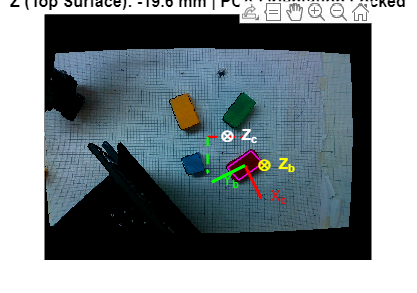


%% -------------------- 6. Visualization --------------------
figure('Name', 'Rectified Block Frame');
imshow(imgRGB); hold on;
plot(rect_x, rect_y, 'm', 'LineWidth', 0.5); % Bounding box
axisLen = 70;

% Block Frame (Body Frame)
quiver(perfect_cx, perfect_cy, axisLen*x_vec(1), axisLen*x_vec(2), 0, 'r', 'LineWidth', 2); 
quiver(perfect_cx, perfect_cy, axisLen*y_vec(1), axisLen*y_vec(2), 0, 'g', 'LineWidth', 2); 
text(perfect_cx, perfect_cy, ' \otimes Z_b', 'Color', 'y', 'FontSize', 10, 'FontWeight', 'bold');
text(perfect_cx + axisLen*x_vec(1), perfect_cy + axisLen*x_vec(2), ' X_b', 'Color', 'r');
text(perfect_cx + axisLen*y_vec(1), perfect_cy + axisLen*y_vec(2), ' Y_b', 'Color', 'g');

% Camera Frame (Origin)
quiver(cx_img, cy_img, axisLen, 0, 0, 'r', 'LineWidth', 1.5, 'LineStyle', '--'); 
quiver(cx_img, cy_img, 0, axisLen, 0, 'g', 'LineWidth', 1.5, 'LineStyle', '--'); 
text(cx_img, cy_img, ' \otimes Z_c', 'Color', 'w', 'FontSize', 10, 'FontWeight', 'bold');

title(sprintf('Z (Top Surface): %.1f mm | PCA Orientation Locked', Z));
hold off;



%% --- Helper Function ---
function [x, y] = findMinRect(hull, maskSize)
    mask = poly2mask(hull(:,1), hull(:,2), maskSize(1), maskSize(2));
    s = regionprops(mask, 'Extrema');
    ex = s.Extrema;
    x = [ex(1,1); ex(3,1); ex(5,1); ex(7,1); ex(1,1)];
    y = [ex(1,2); ex(3,2); ex(5,2); ex(7,2); ex(1,2)];
end